Grant Roberts

03/11/2019

MP574

# Homework 3

## Problem 1: Reconstruction from Partial Fourier Samples without Regularization

**Write a script that loads the data in **`hw3_problem1.mat`**, and reconstructs an image of size 320x320 pixels from the samples in array** `b`. The samples are DFT samples of the image, taken at the locations specified by the mask in array `mask`. In other words, the matrix $\mathbf{A}$ in our general formulation (equation 1 above) is 


$$\mathbf{A}=\mathbf{MF}$$


where $\mathbf{F}$ performs a 2D DFT (including `fftshifts` and `ifftshifts`) and the matrix $\mathbf{M}$ is a sampling matrix that selects a subset of samples from the resulting 320x320 2D DFT. The selected subset of samples is given by the binary array `m`.

In this case, there is no regularization term (ie: $\lambda =0$).

#### Load Data

clear all; close all;
load('hw3_problem1.mat')

imageSize = [320 320]; % image dimensions
N = imageSize(1)*imageSize(2); % total number of pixels
dims = imageSize(1); % = 320
tol = 0.01; % tolerance (for approximate convergence)
iters = 100;

B(m) = b; % zero filled data
B = B(:); % vectorization
tru = reshape(B,imageSize); % original kSpace data
TRU = ifft2c(tru); % original undersampled image

#### Steepest Descent

x = zeros(N,1); % initial image estimation
f = zeros(1,iters); % initialize cost function values

lambda = 0; % no regularization
D = sparse(N,N); % dummy (all zeros, sparse) finite differences matrix
W = ones(dims,dims); % dummy (all ones) weighting matrix

tic
for ii=1:iters
    [f(ii),g] = evalGradients_L2( x,imageSize,b,m,lambda,D,W ); % get gradient and cost function value at x
    alpha = goldenSearch( x,g,imageSize,b,m,lambda,D,W ); % find alpha for this x
    x = x - alpha*g; % take a step (alpha) in grad direction, get new x
    if norm(g) < tol % if gradient is near 0
        break; % the solution converged
    end    
end 
toc

Elapsed time is 3.466533 seconds.



f = f(1:ii); % cutoff trailing zeros
solutionSD = x; % IMAGE SPACE SOLUTION

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

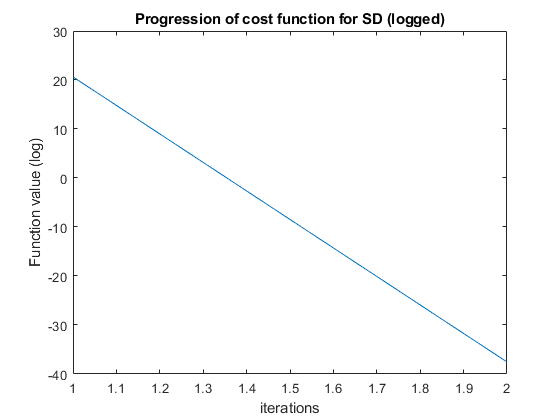

figure; plot(log(f));
title('Progression of cost function for SD (logged)'); xlabel('iterations'); ylabel('Function value (log)')

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

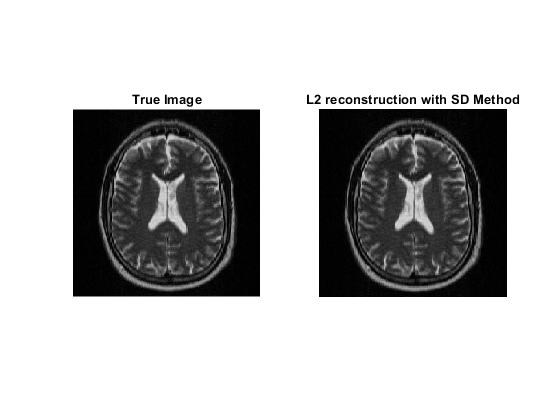

% Show image solution
figure; 
subplot(1,2,1); imshow(abs(TRU),[0 400]); title 'True Image'; 
subplot(1,2,2); imshow(reshape(abs(solutionSD),imageSize),[0 400]); title 'L2 reconstruction with SD Method'

#### Conjugate Gradients

x = zeros(N,1); % initial image estimation
f = zeros(1,iters); % initialize cost function values

tic

[f(1),g] = evalGradients_L2( x,imageSize,b,m,lambda,D,W ); % calculate gradient and cost at initial guess
d = -g;

solution_exists = 0; % set to false
jj = 0;
while(jj < iters && solution_exists == 0)
    jj = jj+1;
        % Create Qd vector
        dK = fft2c(reshape(d,imageSize)); % kSpace d vector (Fd)
        dKm = dK(:).*m; % masked kSpace d vector (M'MFd)
        Qd = ifft2c(reshape(dKm,imageSize)); % back to image space (F'M'MFd)  
    alpha = -(g'*d)/(d'*Qd(:)); % find next stepsize
    x = x + alpha*d; % move that stepsize in direction of gradient (d).
    [f(jj+1),g] = evalGradients_L2( x,imageSize,b,m,lambda,D,W ); % redefine gradient
    if norm(g) < tol % if gradient is near 0
        solution_exists = 1; % BREAK        
    else 
        beta = (g'*Qd(:))/(d'*Qd(:)); % find next-next step
        d = -g + beta*d; % second gradient move
    end
end 
toc

Elapsed time is 0.189463 seconds.



f = f(1:jj+1); % cutoff trailing zeros
solutionCG = x; % IMAGE SPACE SOLUTION

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

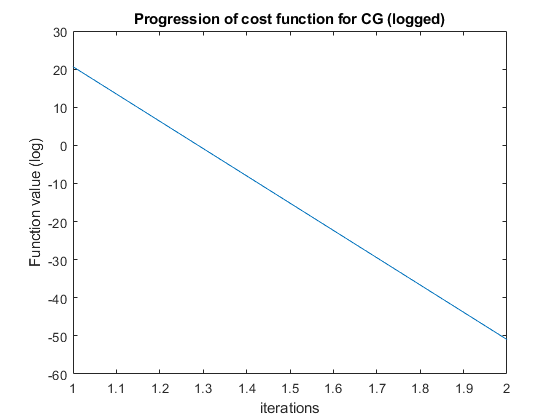

figure; plot(log(f)); 
title('Progression of cost function for CG (logged)'); xlabel('iterations'); ylabel('Function value (log)')

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

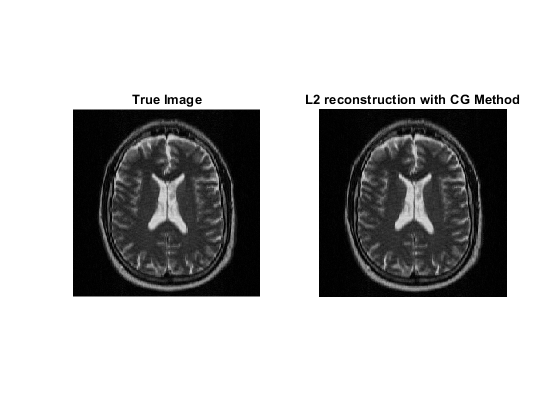

figure; 
subplot(1,2,1); imshow(abs(TRU),[0 400]); title 'True Image'; 
subplot(1,2,2); imshow(reshape(abs(solutionCG),imageSize),[0 400]); title 'L2 reconstruction with CG Method'

- **Report the relative performance of SD and CG (ie: how rapidly do they converge).**

disp(['Steepest Descent method converged in ' num2str(ii) ' iterations']);

Steepest Descent method converged in 2 iterations


disp(['Conjugate Gradient method converged in ' num2str(jj+1) ' iterations']);

Conjugate Gradient method converged in 2 iterations


The CG method was slightly quicker in reaching the global optimum, but both were fairly quick. The SD method took longer (5.7 s) to converge, while the CG method took approximately 82.5 ms to converge.

## Problem 2: Reconstruction from Partial Fourier Samples with Smoothness Regularization

**Write a script that loads the data in **`hw3_problem2.mat`**, and reconstructs an image (320x320 pixels) from the samples in array **`b`. Next we describe the data and smoothness terms:

• Data term: Similar to the previous case, the samples in `b` are DFT samples of the image, taken at the locations specified by the mask in array `mask`. In other words, the matrix $\mathbf{A}$ in our general formulation (equation 1 above) is


$$\mathbf{A}=\mathbf{MF}$$


where $\mathbf{F}$ performs a DFT (including `fftshifts`) and the matrix $\mathbf{M}$ is a sampling matrix that selects a subset of samples from the resulting 320x320 DFT. The selected subset of samples is given by the binary array `m`.

• Smoothness term: The smoothness term is given by $\lambda \;{\left\|\textrm{Cx}\right\|}_2^2$, where $\mathbf{C}=\mathbf{D}$ calculates finite differences in 2D, as described in lecture 14 of this course (where we denoted it as `D2` in the Matlab code to indicate its 2D nature).

You should **repeat this optimization for several different values of **$\lambda$:

• $\lambda ={10}^0$

• $\lambda ={10}^2$

• $\lambda ={10}^4$

• $\lambda ={10}^6$

• $\lambda ={10}^8$

#### Load data

lambda = [10^0 10^2 10^4 10^6 10^8]; % array of each lambda

% Create D (finite differences matrix)
D = 2*eye(dims) - circshift(eye(dims),[0, -1]) - circshift(eye(dims),[0, 1]);
D = sparse(D);
I = speye(dims);
D2 = kron(I,D) + kron(D,I);

#### Steepest Descent

x = zeros(N,1); % set guess as last solution (faster convergence)
f = zeros(1,iters); % initialize cost function values

tic
for ll=1:length(lambda)
    for ii=1:iters
        [f(ii),g] = evalGradients_L2( x,imageSize,b,m,lambda(ll),D2,W ); % calculate gradient and cost at x
        alpha = goldenSearch( x,g,imageSize,b,m,lambda(ll),D2,W ); % find alpha for this x
        x = x - alpha*g; % find new x
        if norm(g) < tol % if gradient is near 0
            break; % the solution converged
        end    
    end   
    fCell{ll} = f(1:ii); % cutoff trailing zeros and store in cell
    solutionCell{ll} = x; % grab solution and store in cell
    itsSD(ll) = ii; % get iteration count for each lambda
    toc
end 

Elapsed time is 187.295927 seconds.
Elapsed time is 386.914146 seconds.
Elapsed time is 585.965870 seconds.
Elapsed time is 776.149666 seconds.


- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

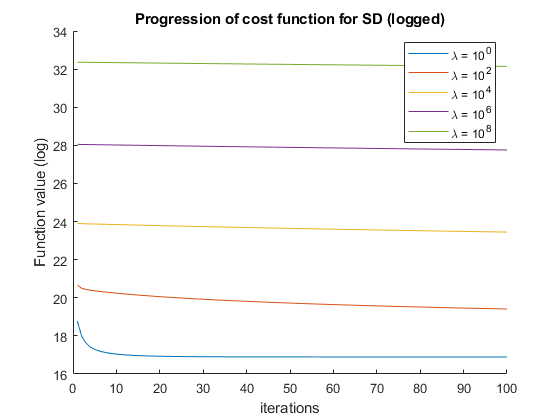

figure; hold on;
for lf=1:length(lambda)
    plot(log(fCell{lf}));
end 
title('Progression of cost function for SD (logged)'); xlabel('iterations'); ylabel('Function value (log)')
legend({'\lambda = 10^0','\lambda = 10^2','\lambda = 10^4','\lambda = 10^6','\lambda = 10^8'});

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

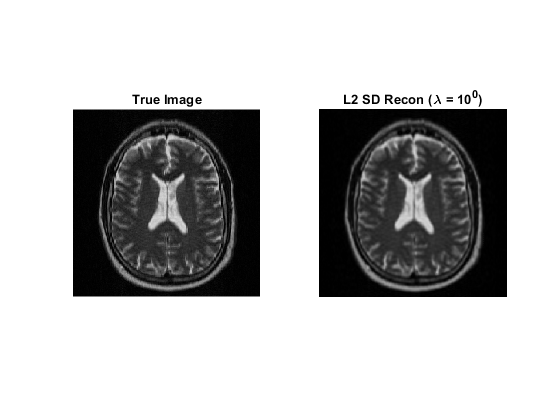

% Show image solution
figure;
subplot(1,2,1); imshow(abs(TRU),[0 400]); title 'True Image'; 
subplot(1,2,2); imshow(reshape(abs(solutionCell{1}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^0)'

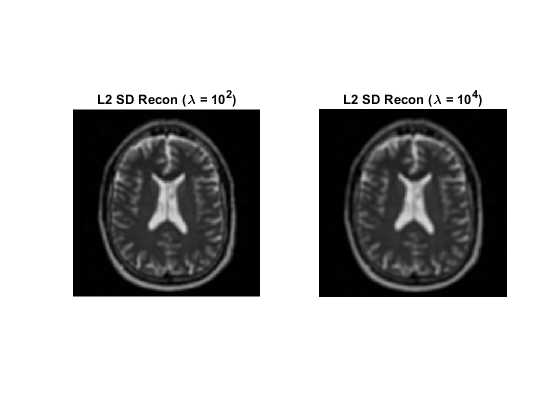

figure;
subplot(1,2,1); imshow(reshape(abs(solutionCell{2}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^2)'
subplot(1,2,2); imshow(reshape(abs(solutionCell{3}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^4)'

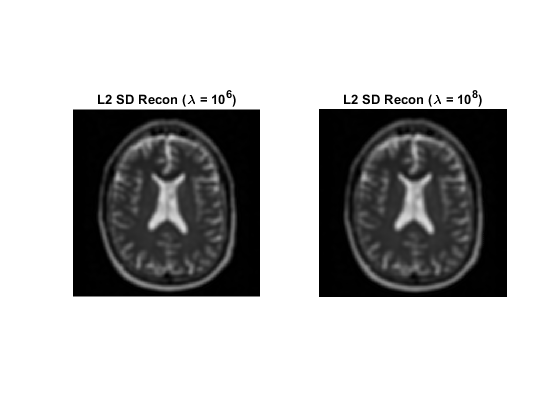

figure;
subplot(1,2,1); imshow(reshape(abs(solutionCell{4}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^6)'
subplot(1,2,2); imshow(reshape(abs(solutionCell{5}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^8)'

#### Conjugate Gradients

x = zeros(N,1); % Initialize kSpace matrix
f = zeros(1,iters); % initialize cost function values

tic
for ll=1:length(lambda)
    [f(1),g] = evalGradients_L2( x,imageSize,b,m,lambda(ll),D2,W ); % calculate gradient and cost at initial guess
    d = -g;
    
    solution_exists = 0; % set to false
    jj = 0;
    while(jj < iters && solution_exists == 0)
        jj = jj+1;
            % Get Q matrix
            dK = fft2c(reshape(d,imageSize)); % kSpace d vector (Fd)
            dK = dK(:).*m; % masked kSpace d vector (M'MFd)
            fxfd = ifft2c(reshape(dK,imageSize));
            Qd = fxfd(:) + lambda(ll)*D2'*(conj(W(:)).*W(:).*(D2*d)); % back to image space (F'M'MFd)  
        alpha = -(g'*d)/(d'*Qd(:)); % find next stepsize
        x = x + alpha*d; % move that stepsize in direction of gradient (d).
        [f(jj+1),g] = evalGradients_L2( x,imageSize,b,m,lambda(ll),D2,W ); % redefine gradient
        if norm(g) < tol % if gradient is near 0
            solution_exists = 1; % BREAK        
        else 
            beta = (g'*Qd(:))/(d'*Qd(:)); % find next-next step
            d = -g + beta*d; % second gradient move
        end
    end       
    fCell{ll} = f(1:jj); % cutoff trailing zeros
    solutionCell{ll} = x; % grab solution
    itsCG(ll) = jj; % get iteration count for each lambda
    toc
    
end 

Elapsed time is 7.978251 seconds.


Index in position 2 is invalid. Array indices must be positive integers or logical values.

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

figure; hold on;
for lf=1:length(lambda)
    plot(log(fCell{lf}));
end 
title('Progression of cost function for CG (logged)'); xlabel('iterations'); ylabel('Function value (log)')
legend({'\lambda = 10^0','\lambda = 10^2','\lambda = 10^4','\lambda = 10^6','\lambda = 10^8'});

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

% Show image solution
figure;
subplot(1,2,1); imshow(abs(TRU),[0 400]); title 'True Image'; 
subplot(1,2,2); imshow(reshape(abs(solutionCell{1}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^0)'
figure;
subplot(1,2,1); imshow(reshape(abs(solutionCell{2}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^2)'
subplot(1,2,2); imshow(reshape(abs(solutionCell{3}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^4)'
figure;
subplot(1,2,1); imshow(reshape(abs(solutionCell{4}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^6)'
subplot(1,2,2); imshow(reshape(abs(solutionCell{5}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^8)'

- **Report the relative performance of SD and CG (ie: how rapidly do they converge).**

disp(['Steepest Descent Method converged in ' num2str(ii) ' iterations']);
disp(['Conjugate Gradient Method converged in ' num2str(jj) ' iterations']);

The CG method was slightly quicker in reaching the global optimum, but both were fairly quick. The SD method took slightly longer (340 ms) to converge, while the CG method took approximately 280 ms to converge.

- **How does the final value of the cost function change as **$\lambda$** increases? How does the visual appearance of the image change as **$\lambda$** increases? **

## Problem 3: Reconstruction from Partial Fourier Samples with Anatomically-Informed Smoothness Regularization 

**Write a script that loads the data in **`hw3_problem3.mat`**, and reconstructs an image (320x320 pixels) from the samples in array **`b`. Next we describe the data and smoothness terms:

• Data term: Similar to the previous case, the samples in `b` are DFT samples of the image, taken at the locations specified by the mask in array `mask`. In other words, the matrix $\mathbf{A}$ in our general formulation (equation 1 above) is


$$\mathbf{A}=\mathbf{MF}$$


where $\mathbf{F}$ performs a DFT (including `fftshifts`) and the matrix $\mathbf{M}$ is a sampling matrix that selects a subset of samples from the resulting 320x320 DFT. The selected subset of samples is given by the binary array `m`.

• Smoothness term: The smoothness term is given by $\lambda \;{\left\|\textrm{Cx}\right\|}_2^2$, where $\mathbf{C}=\mathbf{WD}$ calculates weighted finite differences in 2D. The matrix $\mathbf{D}$, similarly to the previous problem, is as described in lecture 14 of this course (where we denoted it as `D2` in the Matlab code to indicate its 2D nature). The weighting matrix $\mathbf{W}$ is a diagonal matrix with weights derived from an image of the same anatomy as our desired image: it specifies in which locations we will penalize roughness, and in which locations (those with expected edges) we will not penalize roughness. The diagonal elements of this matrix can be found in array `w`.

You should **repeat this optimization for several different values of **$\lambda$:

• $\lambda ={10}^0$

• $\lambda ={10}^2$

• $\lambda ={10}^4$

• $\lambda ={10}^6$

• $\lambda ={10}^8$

and, in each case, **report the cost function as a function of iterations (plot), as well as the final estimated image (display)**. This should be done **for both the SD and the CG algorithms**.

#### Load data

load('hw3_problem3.mat')

#### Steepest Descent

x = zeros(N,1); % Initialize kSpace matrix
f = zeros(1,iters); % initialize cost function values

tic
for ll=1:length(lambda)
    for ii=1:iters
        [f(ii),g] = evalGradients_L2( x,imageSize,b,m,lambda(ll),D2,w ); % calculate gradient and cost
        alpha = goldenSearch( x,g,imageSize,b,m,lambda(ll),D2,w ); % find alpha for this x
        x = x - alpha*g; % find new x
        if norm(g) < tol % if gradient is near 0
            break; % the solution converged
        end    
    end   
    fCell{ll} = f(1:ii); % cutoff trailing zeros and store in cell
    solutionCell{ll} = x; % grab solution and store in cell
    itsSD(ll) = ii; % get iteration count for each lambda
    toc
end 

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

figure; hold on;
for lf=1:length(lambda)
    plot(log(fCell{lf}));
end 
title('Progression of cost function for SD (logged)'); xlabel('iterations'); ylabel('Function value (log)')
legend({'\lambda = 10^0','\lambda = 10^2','\lambda = 10^4','\lambda = 10^6','\lambda = 10^8'});

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

% Show image solution
figure;
subplot(1,2,1); imshow(abs(TRU),[0 400]); title 'True Image'; 
subplot(1,2,2); imshow(reshape(abs(solutionCell{1}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^0)'
figure;
subplot(1,2,1); imshow(reshape(abs(solutionCell{2}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^2)'
subplot(1,2,2); imshow(reshape(abs(solutionCell{3}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^4)'
figure;
subplot(1,2,1); imshow(reshape(abs(solutionCell{4}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^6)'
subplot(1,2,2); imshow(reshape(abs(solutionCell{5}),imageSize),[0 400]); title 'L2 SD Recon (\lambda = 10^8)'

#### Conjugate Gradients

x = zeros(N,1); % Initialize kSpace matrix
f = zeros(1,iters); % initialize cost function values

tic
for ll=1:length(lambda)
    [f(1),g] = evalGradients_L2( x,imageSize,b,m,lambda(ll),D2,w ); % calculate gradient and cost at initial guess
    d = -g; % create new d variable 

    solution_exists = 0; % set to false
    jj = 0;
    while(jj < iters && solution_exists == 0)
        jj = jj+1;
            % Get Q matrix
            dK = fft2c(reshape(d,imageSize)); % kSpace d vector (Fd)
            dK = dK(:).*m; % masked kSpace d vector (M'MFd)
            fxfd = ifft2c(reshape(dK,imageSize));
            Qd = fxfd(:) + lambda(ll)*D2'*(conj(w(:)).*w(:).*(D2*d)); % back to image space (F'M'MFd)  
        alpha = -(g'*d)/(d'*Qd(:)); % find next stepsize
        x = x + alpha*d; % move that stepsize in direction of gradient (d).
        [f(jj+1),g] = evalGradients_L2( x,imageSize,b,m,lambda(ll),D2,w ); % redefine gradient
        if norm(g) < tol % if gradient is near 0
            solution_exists = 1; % BREAK        
        else 
            beta = (g'*Qd(:))/(d'*Qd(:)); % find next-next step
            d = -g + beta*d; % second gradient move
        end
    end 
    fCell{ll} = f(1:jj); % cutoff trailing zeros
    solutionCell{ll} = x; % grab solution
    itsCG(ll) = jj; % get iteration count for each lambda
    toc    
end 

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

figure; hold on;
for lf=1:length(lambda)
    plot(log(fCell{lf}));
end 
title('Progression of cost function for CG (logged)'); xlabel('iterations'); ylabel('Function value (log)')
legend({'\lambda = 10^0','\lambda = 10^2','\lambda = 10^4','\lambda = 10^6','\lambda = 10^8'});

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

% Show image solution
figure;
subplot(1,2,1); imshow(abs(TRU),[0 400]); title 'True Image'; 
subplot(1,2,2); imshow(reshape(abs(solutionCell{1}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^0)'
figure;
subplot(1,2,1); imshow(reshape(abs(solutionCell{2}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^2)'
subplot(1,2,2); imshow(reshape(abs(solutionCell{3}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^4)'
figure;
subplot(1,2,1); imshow(reshape(abs(solutionCell{4}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^6)'
subplot(1,2,2); imshow(reshape(abs(solutionCell{5}),imageSize),[0 400]); title 'L2 CG Recon (\lambda = 10^8)'

- **Report the relative performance of SD and CG (ie: how rapidly do they converge).**

disp(['Steepest Descent Method converged in ' num2str(ii) ' iterations']);
disp(['Conjugate Gradient Method converged in ' num2str(jj-1) ' iterations']);

The CG method was slightly quicker in reaching the global optimum, but both were fairly quick. The SD method took slightly longer (340 ms) to converge, while the CG method took approximately 280 ms to converge.

- **How does the final value of the cost function change as **$\lambda$** increases? How does the visual appearance of the image change as **$\lambda$** increases? How do the cost function and visual appearance of the image in this problem compare to those in the previous problem?**

### ANCILLARY FUNCTIONS

Inverse Fourier transform with shifts

% function x = ifft2c(k)
%     x = ifftshift(ifft2(fftshift(k)));
% end

Forward Fourier transform with shifts

% function k = fft2c(x)
%     k = fftshift(fft2(ifftshift(x)));
% end